# LSTM (Long Short-Term Memory)

clc; 
clear; 
close all;

**Load Data**

% The built-in 'WaveformData' dataset for LSTM
% If your MATLAB cannot find the data, please enter the below command: 
% openExample('nnet/SequenceToOneRegressionUsingDeepLearningExample')
load('WaveformData.mat')
rng("default")

% Total 1000 observations with channel x time-steps matrix
size(data)

ans =         1000           1


data(1:5)

ans = 5×1 cell 배열
    {3×103 double}
    {3×136 double}
    {3×140 double}
    {3×124 double}
    {3×127 double}


% 4 types of labels
categories(labels)

ans = 4×1 cell 배열
    {'Sawtooth'}
    {'Sine'    }
    {'Square'  }
    {'Triangle'}


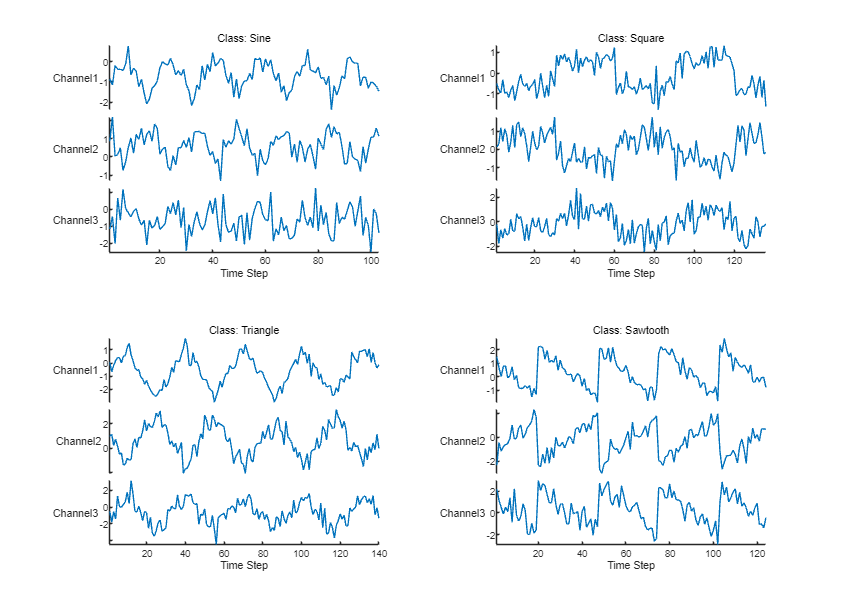

% Plot the waveform according to the labels
% idx = [3 4 5 12];  % if you want to see better shape
idx = [1:4];
numCh = size(data{1},1);

figure('Position', [100 200 940 680]);
tiledlayout(2,2)
for i = 1:length(idx)
    nexttile
    stackedplot( data{idx(i)}', 'DisplayLabels', ["Channel"+string(1:numCh)] );

    xlabel("Time Step")
    title("Class: " + string( labels(idx(i)) ))
end

**Partitioning the train and test data**

n = numel(data);  % sample size

% Partitioning
[idxTrain,idxTest] = trainingPartitions(n, [0.9 0.1]);

X_train = data(idxTrain);
y_train = labels(idxTrain);

X_test = data(idxTest);
y_test = labels(idxTest);

## **LSTM Classification : Sequence-to-One**

% Training
numHiddenUnits = 120;   % Hyperparameter
numClasses = numel( categories(y_train) );

layers = [ ...
    sequenceInputLayer(numCh, Normalization="zscore")
    lstmLayer(numHiddenUnits, OutputMode="last")
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   다음 계층을 포함한 5×1 Layer 배열:

     1   ''   시퀀스 입력   시퀀스 입력 (차원 3개)
     2   ''   LSTM        LSTM (은닉 유닛 120개)
     3   ''   완전 연결     4 완전 연결 계층
     4   ''   소프트맥스    소프트맥스
     5   ''   분류 출력     crossentropyex

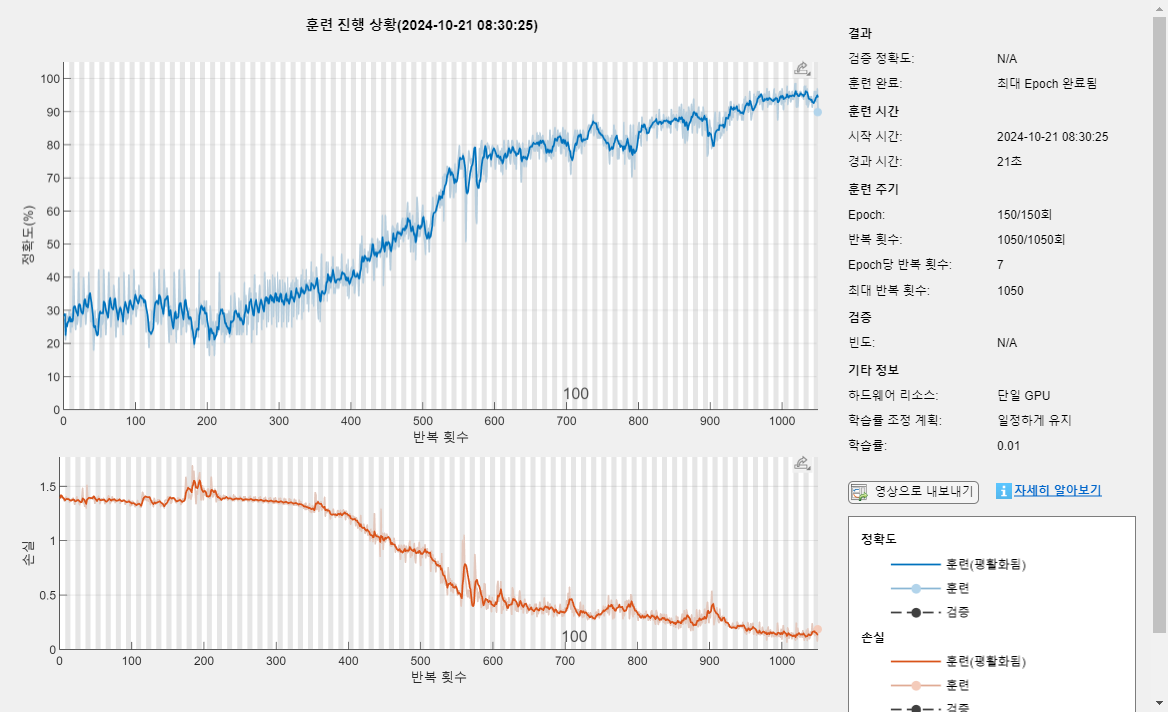

options = trainingOptions("adam", ...
    InitialLearnRate=0.01,...
    MaxEpochs=150, ...
    Shuffle="never", ...
    GradientThreshold=1, ...
    Verbose=false, ...
    Plots="training-progress");

net = trainNetwork(X_train,y_train,layers,options);

% Test
predicted = classify(net,X_test);

acc = mean(predicted == y_test)*100;    % Accuracy
disp(['The LSTM classification accuracy is ' num2str(acc) '%'])

The LSTM classification accuracy is 85%


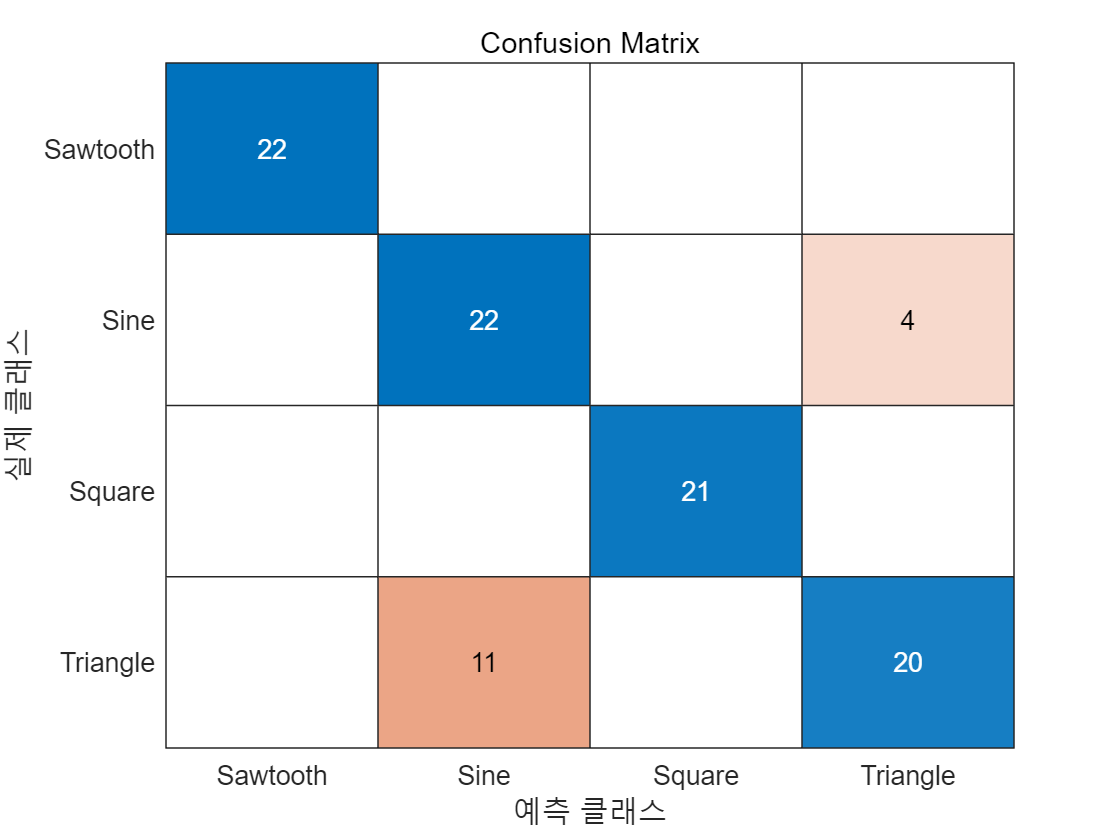

figure
confusionchart(y_test,predicted)    % Confusion matrix
title('Confusion Matrix');

% Forget gate output
X = X_test{2};
sequenceLength = size(X,2);
lstm_L = net.Layers(2, 1);

h = lstm_L.HiddenState; % hidden state
s = lstm_L.CellState;   % cell state

% Extracting weights and biases
U = lstm_L.InputWeights;
W = lstm_L.RecurrentWeights;
b = lstm_L.Bias;

% Indices for the each gate components
input_idx = 1:4:(4*numHiddenUnits);
forget_idx = 2:4:(4*numHiddenUnits);
cand_idx = 3:4:(4*numHiddenUnits);
output_idx = 4:4:(4*numHiddenUnits);

% Extracting the relevant weights and biases for the forget gate
u_f = U(forget_idx, :);
w_f = W(forget_idx, :);
b_f = b(forget_idx);

% Extracting the relevant weights and biases for the input gate
u_g = U(input_idx, :);
w_g = W(input_idx, :);
b_g = b(input_idx);

% Extracting the relevant weights and biases for the ouput gate
u_o = U(output_idx, :);
w_o = W(output_idx, :);
b_o = b(output_idx);

% Extracting the relevant weights and biases for the cell candidate
u_i = U(cand_idx, :);
w_i = W(cand_idx, :);
b_i = b(cand_idx);

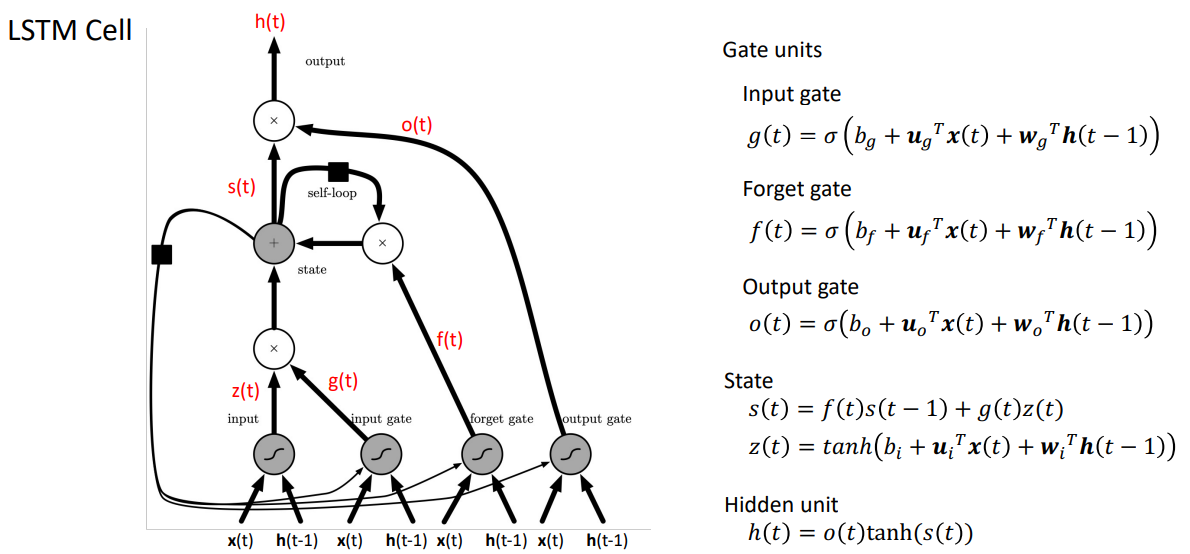

sigma_t = @(t) 1 ./ (1 + exp(-t)); 
for t = 1:sequenceLength
    
    x_t = X(:, t); % Current input
    
    % LSTM forward pass calculations for the forget gate
    forget_gate = sigma_t( b_f + u_f * x_t + w_f * h );

    % input_gate
    input_gate = sigma_t( b_g + u_g * x_t + w_g * h );

    % output_gate
    output_gate = sigma_t( b_o + u_o * x_t + w_o * h );

    % cell_candidates
    cell_candidates = tanh( b_i +  u_i * x_t + w_i * h ); % hyperbolic tangent

    % update the cell state 's(t)' and hidden state 'h(t)' 
    s = forget_gate .* s + input_gate .* cell_candidates; 
    h = output_gate .* tanh(s); 

    % tracking the forget gate's output
    output_f(:, t) = forget_gate;
    % input_f(:, t) = input_gate;
end

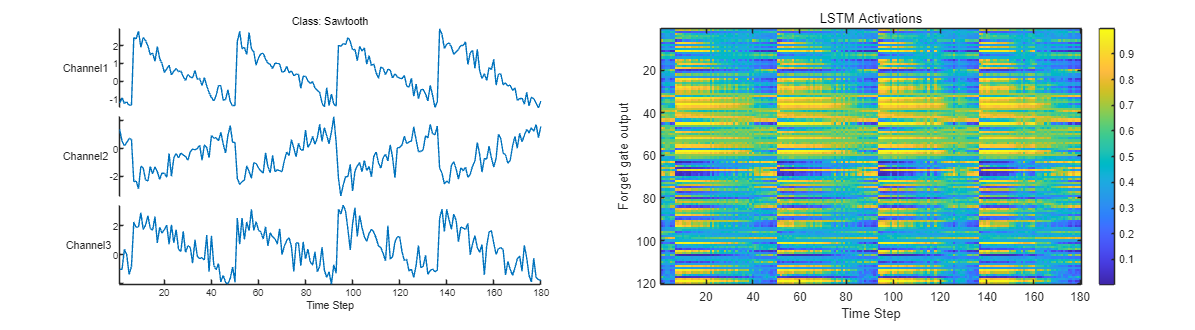

figure('Position',[300 450 1520 420]);
tiledlayout(1,2);
nexttile();
stackedplot(X', DisplayLabels="Channel"+string(1:numCh))
xlabel("Time Step")
title("Class: " + string(y_test(2)))

nexttile();
imagesc(output_f);
colorbar;
xlabel("Time Step")
ylabel("Forget gate output")
title("LSTM Activations")

## **LSTM Regression (Prediction for Next Step) : Sequence-to-One**

#### Prepare Data 

% Set the training set with sequence of 1 ~ (t-1)
% Set the test set with sequence of 2 ~ t
for n = 1:numel(X_train)
    X = X_train{n};
    train_prev{n} = X(:,1:end-1);
    train_next{n} = X(:,2:end);
end

% to stablize training, avoid gradient vanishing and improve generalization
mu_prev = mean(cat(2,train_prev{:}),2);
sigma_prev = std(cat(2,train_prev{:}),0,2);

mu_next = mean(cat(2,train_next{:}),2);
sigma_next = std(cat(2,train_next{:}),0,2);

for n = 1:size(X_test)
    X = X_test{n};
    % Test data also needs to be noramlized 
    % using a statistic calculated from the training data
    test_prev{n} = (X(:,1:end-1) - mu_prev) ./ sigma_prev;
    test_next{n} = (X(:,2:end) - mu_next) ./ sigma_next;
end

**Training**

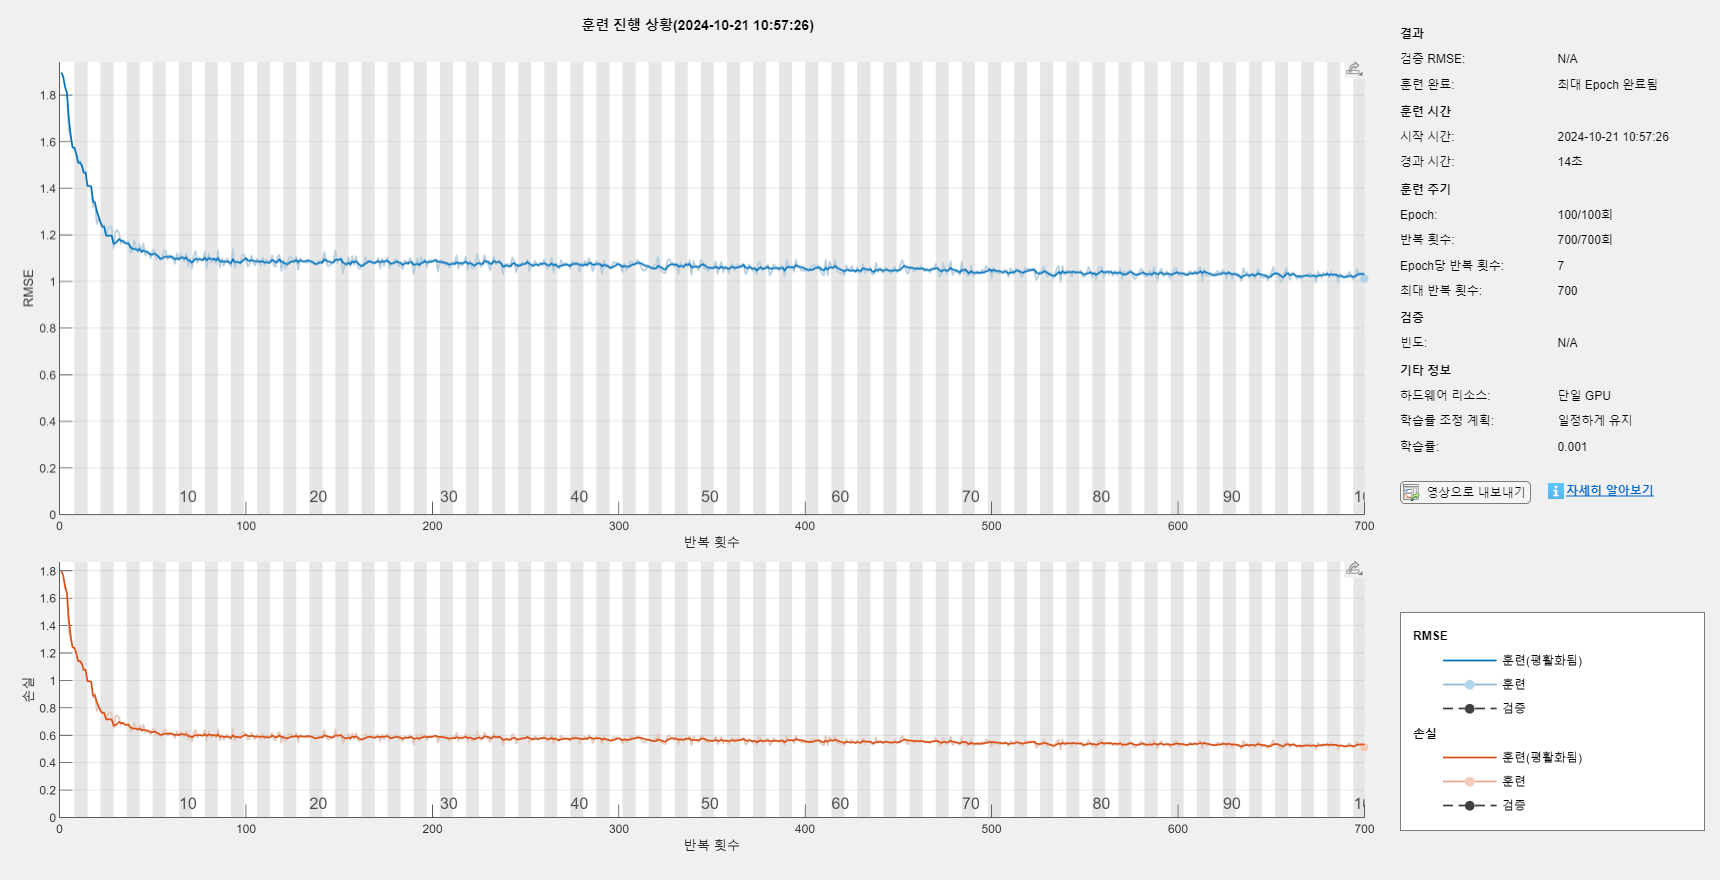

numHiddenUnits = 128;   % Hyperparameter

layers = [
    sequenceInputLayer(numCh, Normalization="zscore")
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numCh)
    regressionLayer];

options = trainingOptions("adam", ...
    MaxEpochs=100, ...
    SequencePaddingDirection="left", ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=0);

net = trainNetwork(train_prev, train_next, layers, options);

**Test**

t_predicted = predict(net,test_prev, SequencePaddingDirection="left");

for i = 1:size(t_predicted,1)
    rmse(i) = sqrt(mean((t_predicted{i} - test_next{i}).^2,"all"));
end

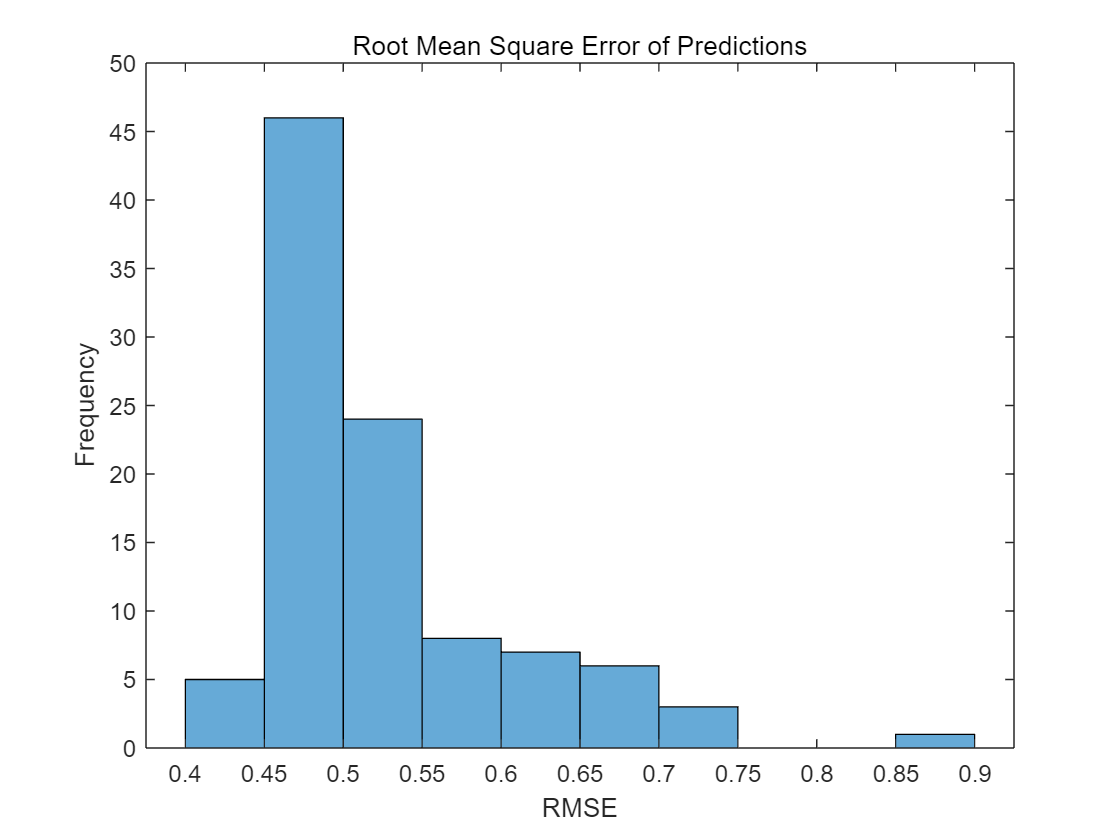

figure
histogram(rmse)
xlabel("RMSE")
ylabel("Frequency")
title('Root Mean Square Error of Predictions')

disp(['The LSTM regression error(RMSE) is ' num2str(mean(rmse))]);

The LSTM regression error(RMSE) is 0.52607


**Forecasting Future time-steps (t+1 ~ ...)**

idx = 12; % example observation
X = test_prev{idx};
X_hat = test_next{idx};

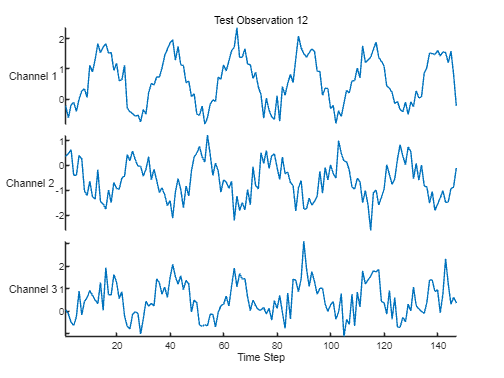

% plot the example observation
figure;                
stackedplot(X',DisplayLabels="Channel " + (1:numCh))
xlabel("Time Step")
title("Test Observation " + idx)

**1) Open Loop Forecasting**

net = resetState(net);      % reset RNN State parameters

offset = 75;                % the number of time-step to use for initial prediction

[net,~] = predictAndUpdateState(net, X(:,1:offset));

numTimeSteps = size(X,2);
numPredictionTimeSteps = numTimeSteps - offset;
Y = zeros(numCh,numPredictionTimeSteps);

for t = 1:numPredictionTimeSteps
    Xt = X(:,offset+t);     % Xt : wants to predict 
    [net,Y(:,t)] = predictAndUpdateState(net,Xt);   % RNN update
end

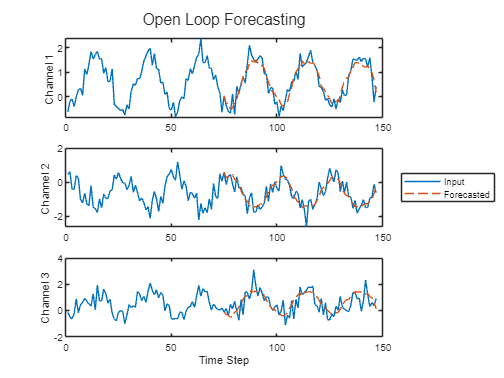

figure;  % Comparison between original data and predicted data
t = tiledlayout(numCh,1);
title(t,"Open Loop Forecasting")
for i = 1:numCh
    nexttile
    plot(X_hat(i,:))
    hold on
    plot(offset:numTimeSteps,[X_hat(i,offset) Y(i,:)],'--')
    ylabel("Channel " + i)
end
xlabel("Time Step")
lg = legend(["Input" "Forecasted"]);
lg.Layout.Tile = 'east';

**2) Closed  Loop Forecasting**

net = resetState(net);      % reset RNN State parameters

offset = size(X,2);         % use all time-sptes for initial prediction

[net,Z] = predictAndUpdateState(net,X);    

numPredictionTimeSteps = 500;
Xt = Z(:,end);
Y = zeros(numCh,numPredictionTimeSteps);

for t = 1:numPredictionTimeSteps
    [net,Y(:,t)] = predictAndUpdateState(net,Xt);
    Xt = Y(:,t);
end

numTimeSteps = offset + numPredictionTimeSteps;

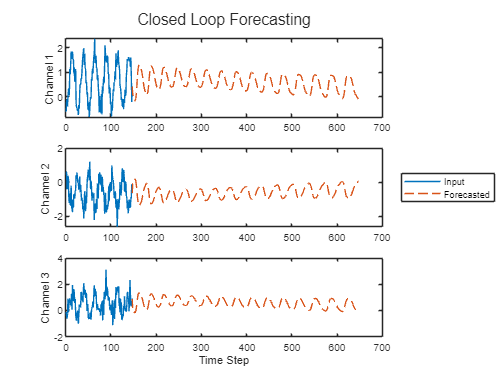

figure  % Plot the predictions
t = tiledlayout(numCh,1);
title(t,"Closed Loop Forecasting")
for i = 1:numCh
    nexttile
    plot(X_hat(i,1:offset))
    hold on
    plot(offset:numTimeSteps,[X_hat(i,offset) Y(i,:)],'--')
    ylabel("Channel " + i)
    % xlim([0 200])
end
xlabel("Time Step")
lg = legend(["Input" "Forecasted"]);
lg.Layout.Tile = 'east';